# Classification by Logistic Regression

## Prepare Data

Load data, remove all rows with missing values and create a binary resonse variable `BPClass` for high blood pressure (BP). Use the two classes 0 and 1:

1 $\colon =$ high BP $\colon =$ `BPSyst1` $\geq 140$ or `BPDias1` $\geq 90$

0 $\colon =$ normal BP $\colon =$ `BPSyst1` $< 140$ and `BPDias1` $< 90$

load healthdata.mat
data = rmmissing(data);
idx = data.BPDias1 == 0;
data = data(~idx,:); %remove all rows with diastolic blood pressure 0
BPClass = double(data.BPSyst1 >= 140 | data.BPDias1 >= 90);

Continuous predictors to use from the data.

preds = {'BMI','ArmLength','Weight','Pulse',...
     'Age','LegLength','ArmCirc','Height','Triceps','Subscapular','Waist'};

Make new table with predictors subject to normalization and add BPClass as a response variable.

tab = data(:,preds);
tab = varfun(@zscore,tab);
tab.BPClass = BPClass;

Divide data in training and test set.

part = cvpartition(tab.BPClass,'HoldOut',0.4);
tridx = training(part);
train = tab(tridx,:);
test = tab(~tridx,:)

test = 1667×12 table
    zscore_BMI    zscore_ArmLength    zscore_Weight    zscore_Pulse    zscore_Age    zscore_LegLength    zscore_ArmCirc    zscore_Height    zscore_Triceps    zscore_Subscapular    zscore_Waist    BPClass
    __________    ________________    _____________    ____________    __________    ________________    ______________    _____________    ______________    __________________    ____________    _______
      0.59121          0.29972            0.4423          0.42029         1.4177          -1.6191            0.52097         -0.099371         -0.29179            

Upsample training data.

train_high = train(train.BPClass == 1,:);
train_low = train(train.BPClass == 0,:);
n = height(train_low);
train = datasample(train_high,n);
train = [train;train_low]

train = 4114×12 table
    zscore_BMI    zscore_ArmLength    zscore_Weight    zscore_Pulse    zscore_Age    zscore_LegLength    zscore_ArmCirc    zscore_Height    zscore_Triceps    zscore_Subscapular    zscore_Waist    BPClass
    __________    ________________    _____________    ____________    __________    ________________    ______________    _____________    ______________    __________________    ____________    _______
       0.76596          2.3556             1.8599        -0.54122         1.4177          0.88274             1.0634            1.8839         -0.66265           

This is one (frequently used) possibility to get a model with an acceptable false negative rate. Another possibility would be to adjust the classification threshold. 

## Fit logistic regression model and predict values on test data

mdl = fitglm(train,'interactions','Distribution','binomial','Link','logit')

mdl = Generalized linear regression model:
    BPClass ~ [Linear formula with 67 terms in 11 predictors]
    Distribution = Binomial

Estimated Coefficients:
                                            Estimate        SE         tStat        pValue   
                                           __________    ________    _________    ___________
    (Intercept)                               0.31371     0.49241       0.6371        0.52406
    zscore_BMI                                 -55.99       35.15      -1.5929        0.11119
    zscore_ArmLength                         0.044744    0.094345      0.47426        0.63531
    zscore_Weight                               64.52      40.504       1.5929        0.11118
    zscore_Pulse                             0.063895    

pr = predict(mdl,test);

Logisitc regression predicts probabilites. Classify all predictions with probability greater than 50% as positives.

class = double(pr > 0.5);

Visualize predictions: as confusion matrix...

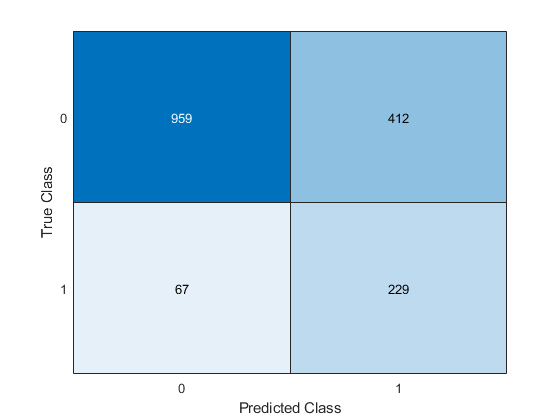

cm = confusionmat(test.BPClass,class);
h = heatmap(cm);
h.XLabel = 'Predicted Class';
h.YLabel = 'True Class';
h.ColorbarVisible = false;
h.XDisplayLabels = {0;1};
h.YDisplayLabels = {0;1};

... and as histogram.

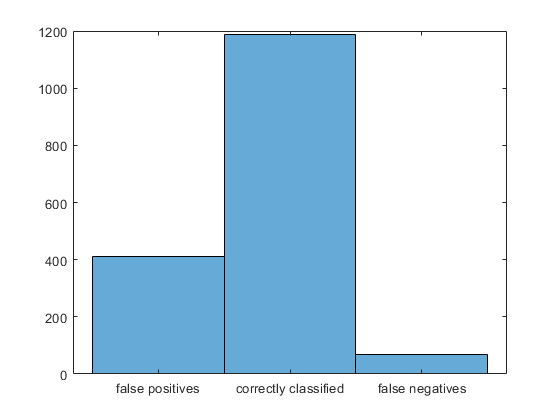

err = test.BPClass - class;
figure
histogram(err)
xticks([-1,0,1])
xticklabels({'false positives','correctly classified','false negatives'})

## Compute some binary classification performance numbers

Accuracy = fraction of test subjects identified correctly

accuracy = sum(diag(cm))/height(test) 

accuracy = 0.7127

Precision = fraction of positively classified actually being positive 

precision = cm(2,2)/sum(cm(:,2))  

precision = 0.3573

Sensitivity = fraction of actual positives classified as positives (true positive rate)

sensitivity = cm(2,2)/sum(cm(2,:))

sensitivity = 0.7736

Specificity = fraction of actual negatives classified as negatives (true negative rate)

specificity = cm(1,1)/sum(cm(1,:))

specificity = 0.6995

Informedness = Sensitivity + Specificity - 1 (Youden's J statistic), a possible measure for the quality of the model

informedness = sensitivity + specificity - 1

informedness = 0.4731